# Perform PCA-ICA analysis to find co-activity patterns

- PCA - find the number of stable components 

- ICA - use the number of stable components to extract co-activity pattens 

load('em_18p_th0.5.mat');
ca_cl=em{1,1}.ca_cl;
for i=1:3
    figure(i)
    t1=tiledlayout(3,4);
    for p=6*(i-1)+1:6*i
        for m=1:2
            [U,V,x,cx,rst1tr,rst1te,rst2tr,rst2te]=stability_dimensions(ca_cl{p,m});
            figure(i)
            nexttile
            plot(cx, '.-')
            title(sprintf('exp %d mouse %d', p, m))
            hold on, plot(xlim, [0 0], 'k--'); hold off
            ndim(p,m)=find(sum([1,cx(3:end)>0.2;cx(3:end)>0.2,1])==0,1); % from the 3 dimension, keep dimensions until stability <0.2
        end
    end
end

Using the derived number of components perform pca followed by ica

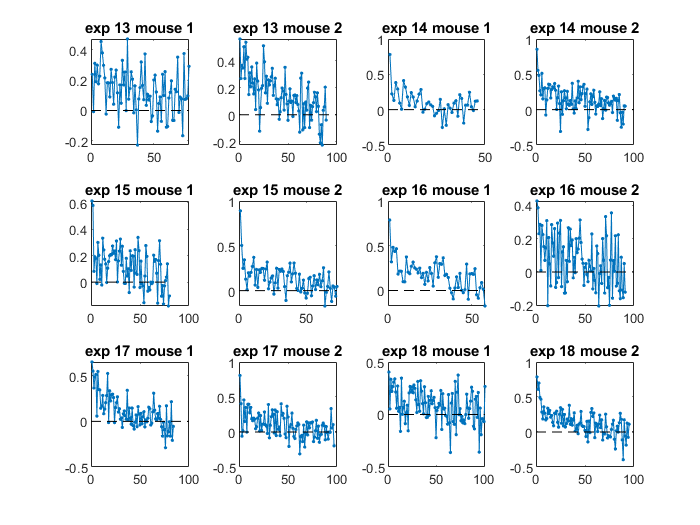

for p=1:18
    [~,score]=pca(ca_cl{p,1}'); % pca on all neurons

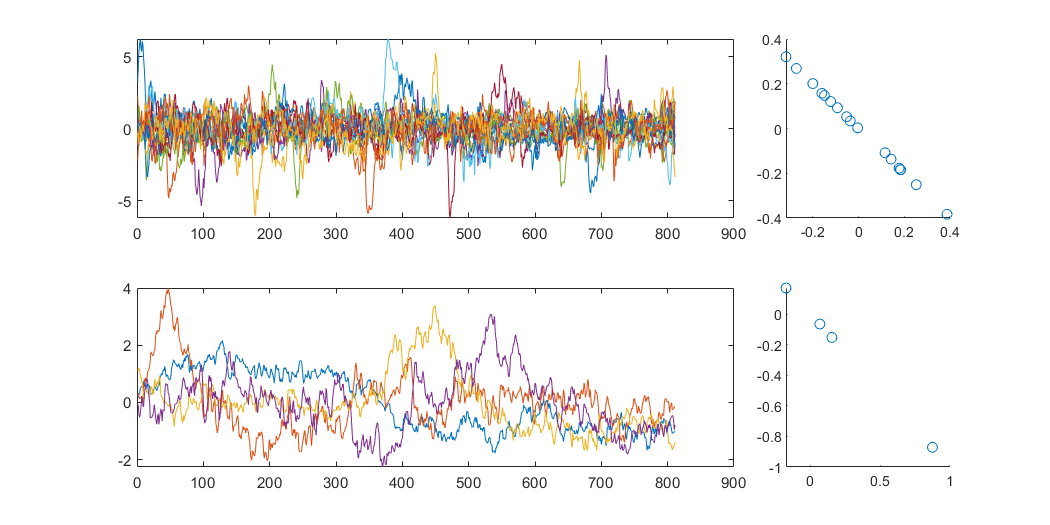

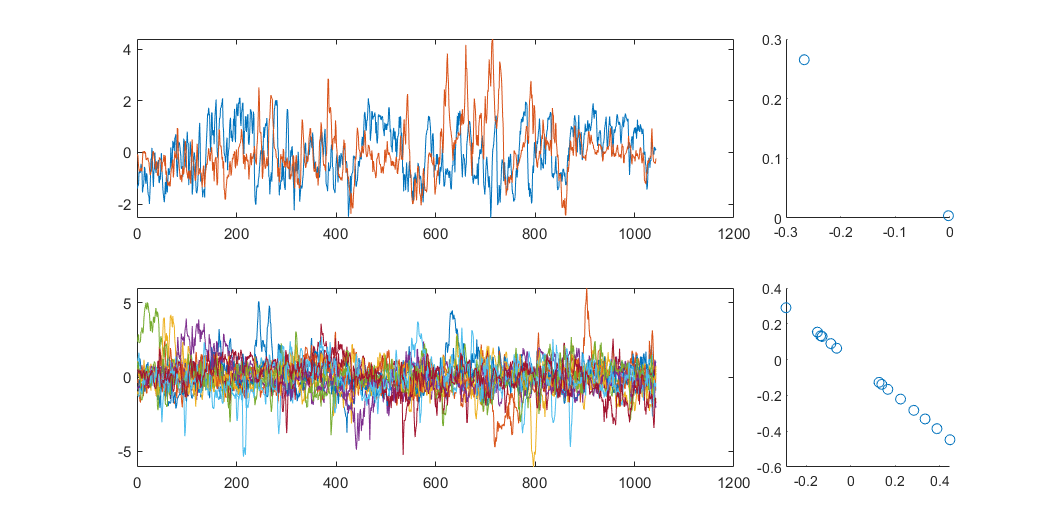

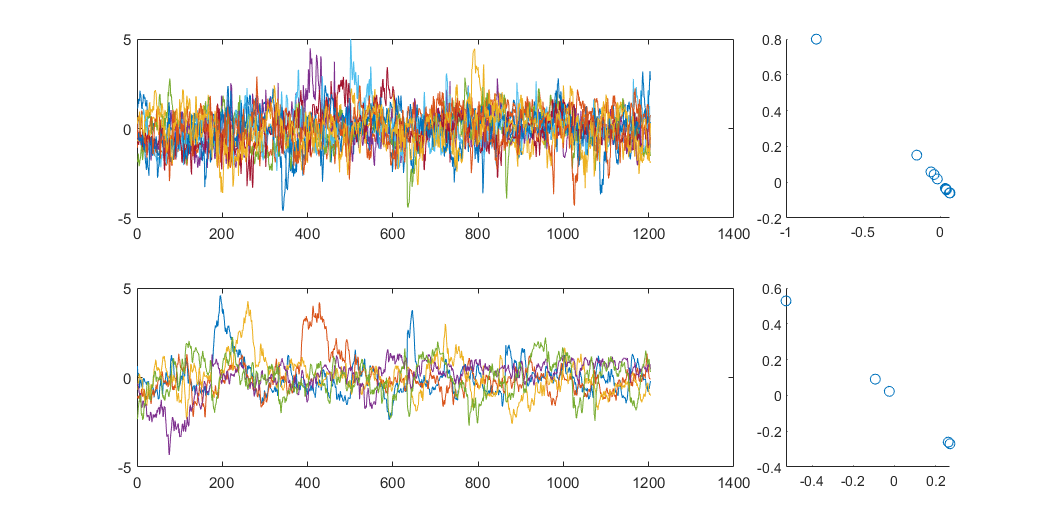

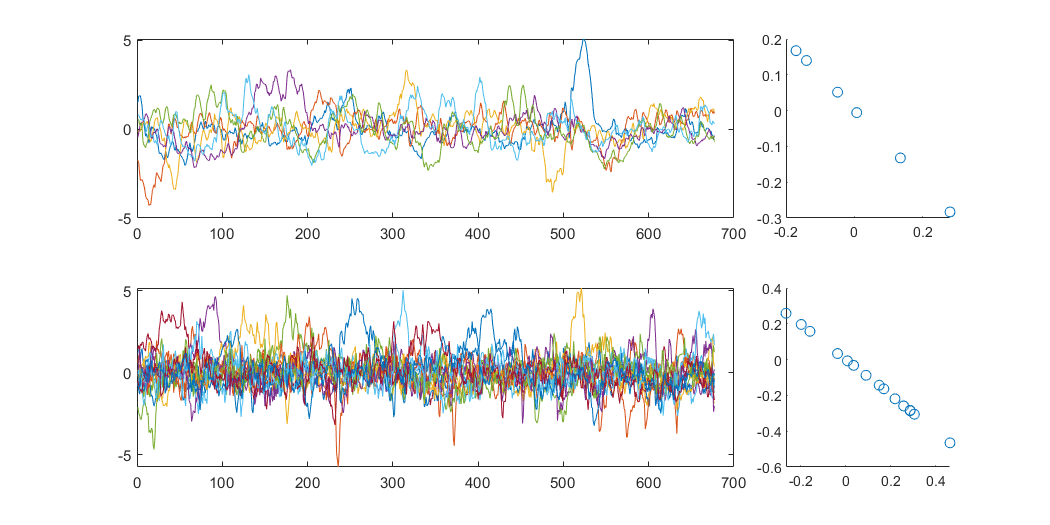

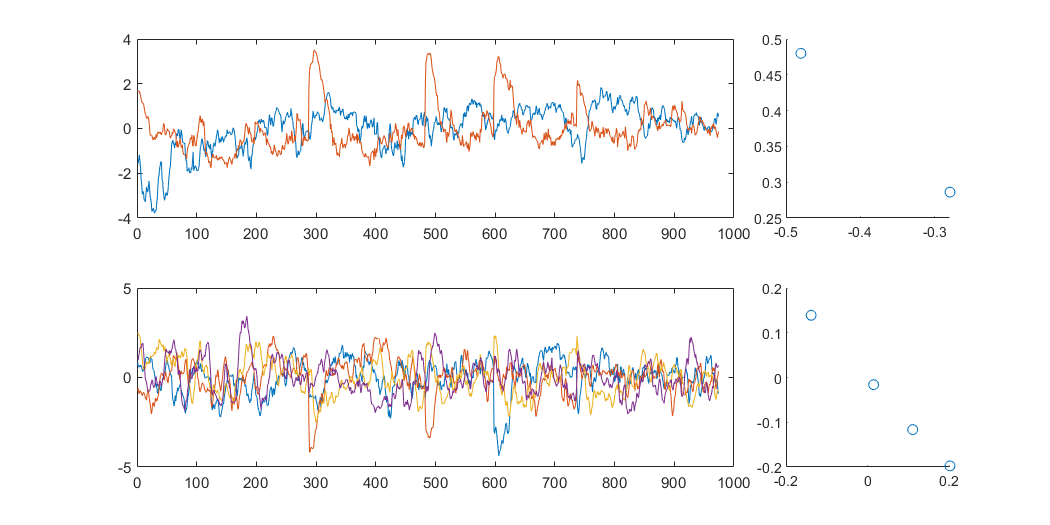

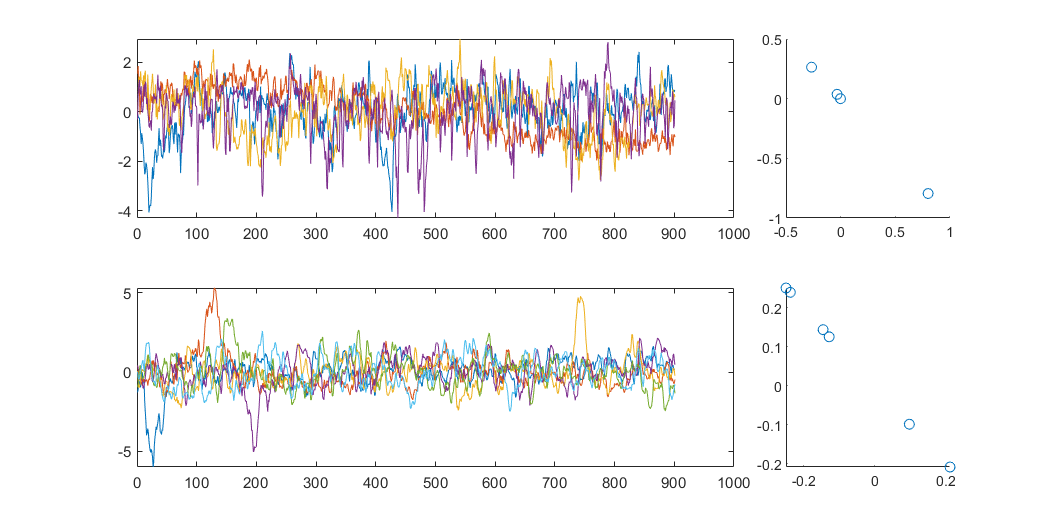

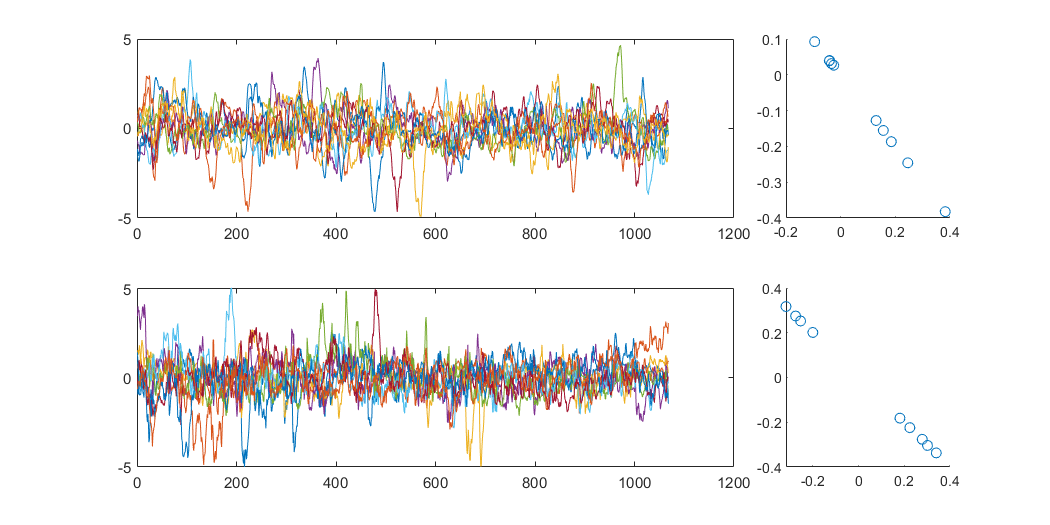

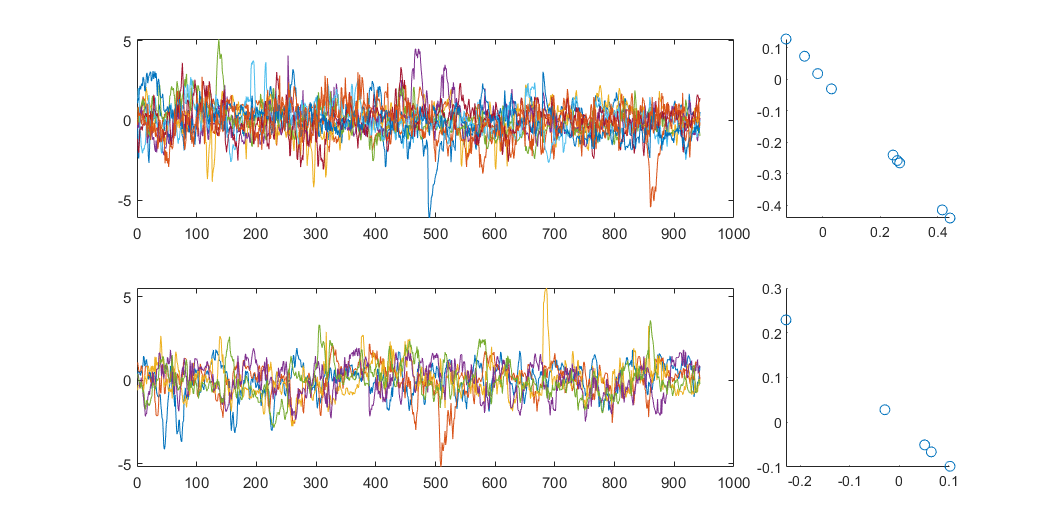

    [ic, A, W]=fastica(score(:,1:ndim(p,1))','verbose','off'); % ica on the first n pcs
    f=figure;f.Position(3)=1.5*f.Position(3);
    subplot(2,4,1:3)
    plot(ic')
    subplot(2,4,4)
    % get distribution of score across two part of signal 
    scatter(mean(ic(:,1:floor(end/2)),2),mean(ic(:,floor(end/2):end),2));
    [~,score]=pca(ca_cl{p,2}');
    [ic, A, W]=fastica(score(:,1:ndim(p,2))','verbose','off');
    subplot(2,4,5:7)
    plot(ic')
    subplot(2,4,8)
    scatter(mean(ic(:,1:floor(end/2)),2),mean(ic(:,floor(end/2):end),2));
end
